linearA = load('dataLinearA.mat');
linearAmeanVoltDataVSRef = linearA.meanVoltDataVSRef; 
linearAmeasureX = linearA.measureX;

linearB = load('dataLinearB.mat');
linearBmeanVoltDataVSRef = linearB.meanVoltDataVSRef; 
linearBmeasureX = linearB.measureX;

rotaryA = load('dataAngularA.mat');
rotaryAmeanVoltDataVSRef = rotaryA.meanVoltDataVSRef; 
rotaryAmeasureX = rotaryA.measureX;

rotaryB = load('dataAngularB.mat');
rotaryBmeanVoltDataVSRef = rotaryB.meanVoltDataVSRef;
rotaryBmeasureX = rotaryB.measureX; 

rotaryC = load('dataAngularC.mat');
rotaryCmeanVoltDataVSRef = rotaryC.meanVoltDataVSRef; 
rotaryCmeasureX = rotaryC.measureX;

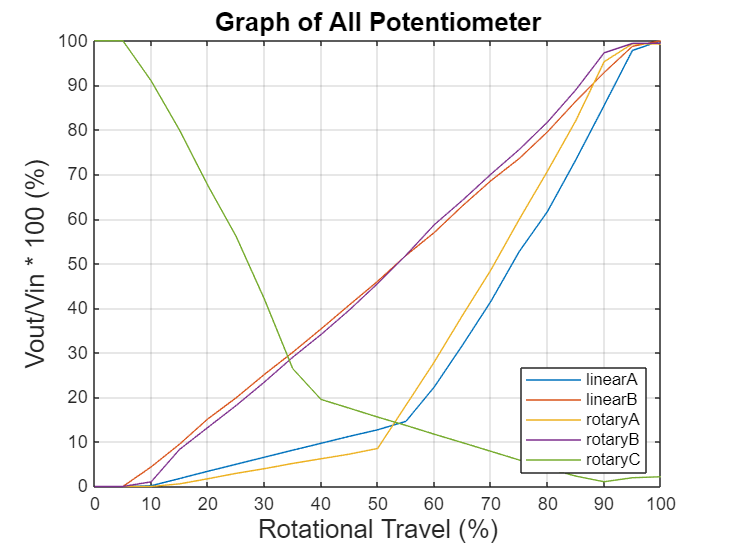

plot(linearAmeasureX, linearAmeanVoltDataVSRef, '-', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
hold on; 
plot(linearBmeasureX, linearBmeanVoltDataVSRef, '-', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
plot(rotaryAmeasureX, rotaryAmeanVoltDataVSRef, '-', 'MarkerSize', 3, 'MarkerEdgeColor', '#FFD700', 'MarkerFaceColor', '#FFD700');
plot(rotaryBmeasureX, rotaryBmeanVoltDataVSRef, '-', 'MarkerSize', 3, 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');
plot(rotaryCmeasureX, rotaryCmeanVoltDataVSRef, '-', 'MarkerSize', 3, 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');
hold off;
% Add on
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Graph of All Potentiometer', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 
legend('linearA', 'linearB', 'rotaryA', 'rotaryB', 'rotaryC','Location', 'southeast');